tffile='063.tfi';
tf=ReadTF(tffile)

tf =          0         0         0         0         0
    0.0303    1.0000         0         0    0.0118
    0.0606    1.0000    0.1843         0    0.0118
    0.0909    1.0000    0.3725         0    0.0078
    0.1212    1.0000    0.5608         0    0.0039
    0.1515    1.0000    0.7490         0         0
    0.1818    1.0000    0.9373         0         0
    0.2121    0.8745    1.0000         0         0
    0.2424    0.6863    1.0000         0         0
    0.2727    0.4980    1.0000         0    0.0039


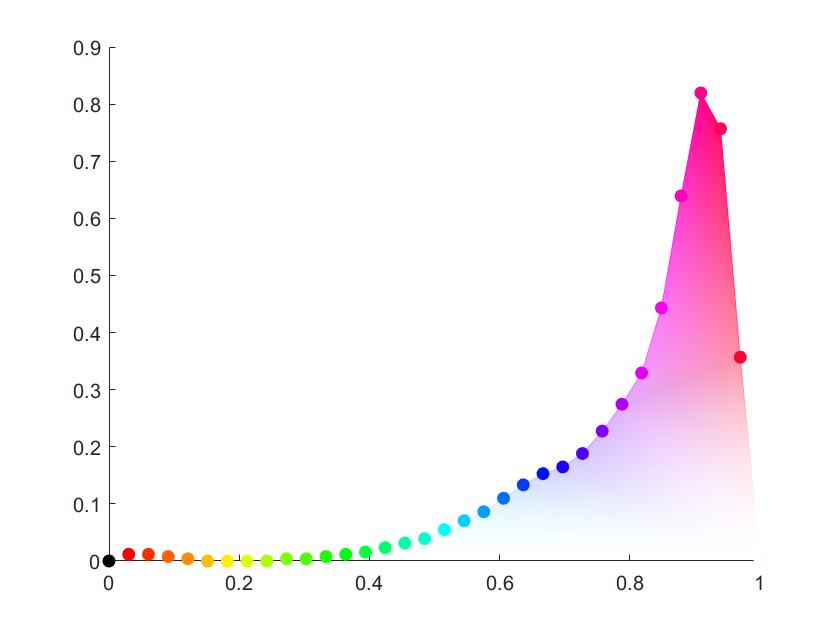

ShowTF(tf)

[~,name,~]=fileparts(tffile);
WriteTF(tf, [name,'.xml'])

function result = ReadTF(tffile)
    xDoc=xmlread(tffile);
    intensityList=xDoc.getElementsByTagName('intensity');
    colorLList=xDoc.getElementsByTagName('colorL');
    range=0:min(intensityList.getLength,colorLList.getLength)-1;
    intensity=arrayfun(@(i) str2double(intensityList.item(i).getAttribute('value')),range);
    r=arrayfun(@(i) str2double(colorLList.item(i).getAttribute('r'))/255,range);
    g=arrayfun(@(i) str2double(colorLList.item(i).getAttribute('g'))/255,range);
    b=arrayfun(@(i) str2double(colorLList.item(i).getAttribute('b'))/255,range);
    a=arrayfun(@(i) str2double(colorLList.item(i).getAttribute('a'))/255,range);
    result=[intensity;r;g;b;a].';
end

function ShowTF(tf)
    a=tf(:,5);
    mymap=tf(:,2:4);
    data=tf(:,[1 5]);
    faces=1:length(a);
    patch('Vertices',data,'Faces',faces,'FaceVertexCData',mymap,'FaceVertexAlphaData',a,'EdgeColor','interp','EdgeAlpha','interp','FaceColor','interp','FaceAlpha','interp','Marker','o','MarkerFaceColor','flat');
end

function WriteTF(tf, tffile)    
    docNode = com.mathworks.xml.XMLUtils.createDocument('VoreenData');
    docNode.appendChild(docNode.createComment('This is a Voreen transfer function created using MATLAB.'));
    docRootNode = docNode.getDocumentElement;
    docRootNode.setAttribute('version','1');
    TransFuncIntensity=docNode.createElement('TransFuncIntensity');
    TransFuncIntensity.setAttribute('type','TransFuncIntensity');
    alphaMode=docNode.createElement('alphaMode');
    alphaMode.setAttribute('value','1');
    gammaValue=docNode.createElement('gammaValue');
    gammaValue.setAttribute('value','1');
    domain=docNode.createElement('domain');
    domain.setAttribute('x','0');
    domain.setAttribute('y','1');
    threshold=docNode.createElement('threshold');
    threshold.setAttribute('x','0');
    threshold.setAttribute('y','1');
    Keys=docNode.createElement('Keys');
    docRootNode.appendChild(TransFuncIntensity);
    TransFuncIntensity.appendChild(alphaMode);
    TransFuncIntensity.appendChild(gammaValue);
    TransFuncIntensity.appendChild(domain);
    TransFuncIntensity.appendChild(threshold);
    TransFuncIntensity.appendChild(Keys);
    
    tfi=[tf(:,1) round(tf(:,2:5).*255)];
    m = size(tf,1);
    for i=1:m
        key = docNode.createElement('key');
        key.setAttribute('type','TransFuncMappingKey');
        intensity = docNode.createElement('intensity');
        intensity.setAttribute('value',num2str(tfi(i,1)));
        split = docNode.createElement('split');
        split.setAttribute('value','false');
        colorL = docNode.createElement('colorL');
        colorL.setAttribute('r',num2str(tfi(i,2)));
        colorL.setAttribute('g',num2str(tfi(i,3)));
        colorL.setAttribute('b',num2str(tfi(i,4)));
        colorL.setAttribute('a',num2str(tfi(i,5)));
        key.appendChild(intensity);
        key.appendChild(split);
        key.appendChild(colorL);
        Keys.appendChild(key);
    end
    
    xmlwrite(tffile,docNode);
end